# Classify Objects with Pretrained Network

In this exercise, you will explore different pretrained networks and see how they classify different objects. 

clear
addpath(genpath(pwd))

Pick one of three networks to load in.

net = alexnet;

## Inspect network

% Inspect network's layers
% analyzeNetwork(net);
net.Layers

% Inspect the different classes available
% Look at the last layer in the network
classes = net.Layers(end).ClassNames


## Classify the images in the folder

Try reading in a few of the images and display them

im = imread(['02-Images',filesep,'file01.jpeg']);
imshow(im)

Based on your network, you'll have to look at the first layer to determine how to resize your image. Use the following command to see input size

net.Layers(1).InputSize

ans =    227   227     3


inputSize = net.Layers(1).InputSize(1:2);

`Resize your the images and classify them.`

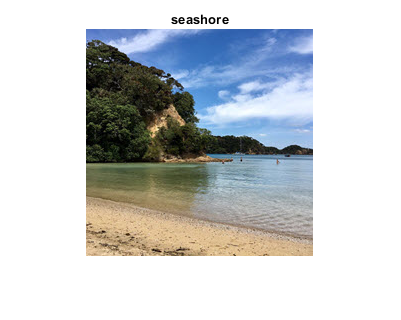

im = imresize(im, inputSize);
label = classify(net,im);
title(char(label))

## Run this in a loop using datastore

A datastore can be used when we have lots of images that we can't load into memory at once. It serves as a way to point to a collection of images when we need them without reading them directly into MATLAB at once. (See [imageDatastore documentation](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.imagedatastore.html) for more details)

You can manage and read images with the datastore:

- `hasdata: `determines if data is available to read

- `read`: imports images one-by-one in consecutive order (used for loops)

- `readimage`: imports a select image

- `readall`: imports all images

Create the datastore for the entire image directory. 

imgPath = '02-Images';
ids = imageDatastore(imgPath)

ids =   ImageDatastore with properties:

                       Files: {
                              ' ...\02-PretrainedModelExercise\02-Images\file01.jpeg';
                              ' ...\02-PretrainedModelExercise\02-Images\file02.jpeg';
                              ' ...\02-PretrainedModelExercise\02-Images\file03.jpeg'
                               ... and 9 more
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @readDatastoreImage


Read, resize, and classify all images one at a time.

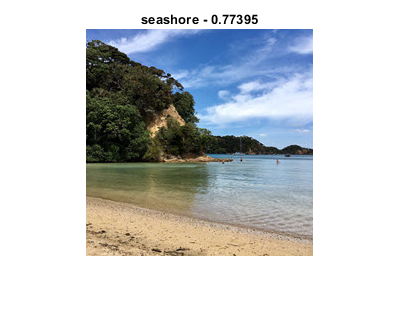

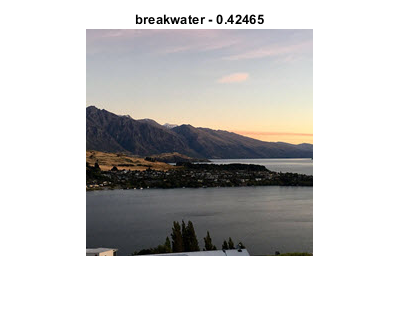

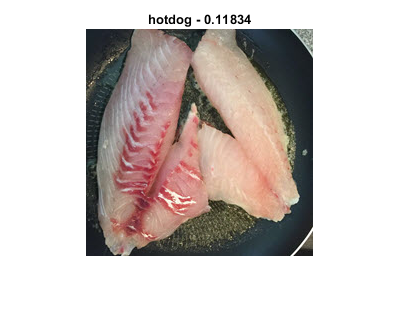

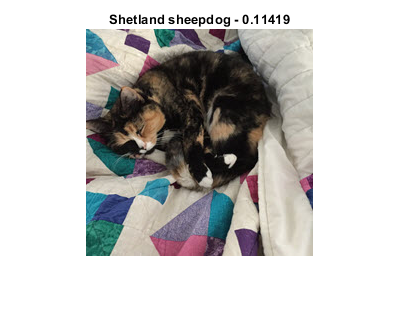

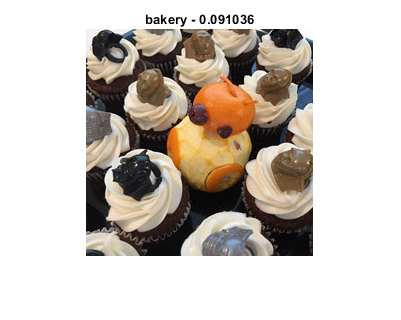

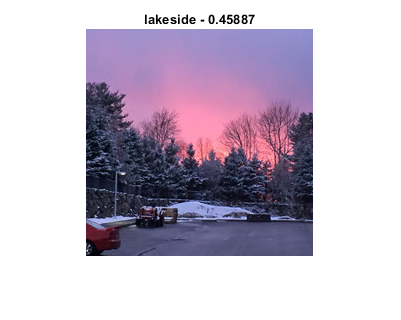

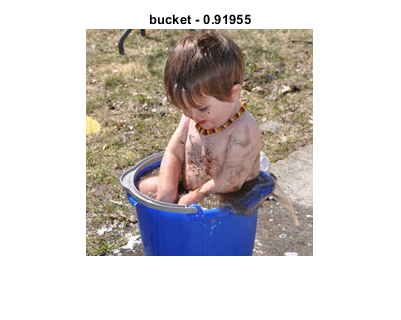

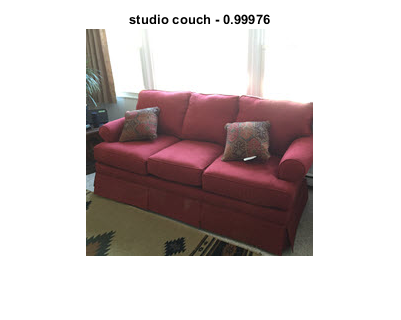

while hasdata(ids)
    
    im = read(ids);
    imR = imresize(im, inputSize);  
    [label,score] = classify(net,imR);
    maxScore = max(score);
    figure
    imshow(im)
    title([char(label) ' - ' num2str(maxScore)])
   
end


ids.reset

## Classify pictures from the internet

URL = 'http://elelur.com/data_images/mammals/monkey/monkey-02.jpg';
filename = 'MonkeyPicture.jpg';
websave(filename, URL);

im = imread('MonkeyPicture.jpg');
im = imresize(im, inputSize);
classify(net,im)

ans = categorical
     macaque 


*Copyright 2019 The MathWorks, Inc.*